larger_pixel_in_FoV=50;
compressing_factor=4;

smaller_pixel_in_FoV=larger_pixel_in_FoV*compressing_factor;
total_smaller_pixel=smaller_pixel_in_FoV+compressing_factor-1;

% Getting input
image_series=create_shifted_images(larger_pixel_in_FoV,compressing_factor); % The first parameter could be an image, or an integer to indicate the number of larger pixels that we want in a row.
GT=image_series{1,1};
compressed_series=compress(image_series,compressing_factor);


% Setting up assumptions of redundants
% Assumptions are filled with numbers, while the unknowns remain as NaN.

all_pixels=zeros(total_smaller_pixel,total_smaller_pixel);
all_pixels(:)=NaN;

% Setting the right small pixels to the right values of compressed_series{1,end}
for i=1:larger_pixel_in_FoV
    all_pixels(1+(i-1)*compressing_factor:i*compressing_factor,smaller_pixel_in_FoV+1:end)=compressed_series{1,end}(i,end)/compressing_factor^2;
end

% Setting the lower right pixels
all_pixels(smaller_pixel_in_FoV+1:end,smaller_pixel_in_FoV+1:end)=compressed_series{end,end}(end,end)/compressing_factor^2;

% Setting the bottom pixels
for i=1:larger_pixel_in_FoV
    all_pixels(smaller_pixel_in_FoV+1:end,1+(i-1)*compressing_factor:i*compressing_factor)=compressed_series{end,1}(end,i)/compressing_factor^2;
end

% generate A

% A is the actual image information that we got. It has a size of (compressing_factor^2*larger_pixel_in_FoV^2)*(total_smaller_pixel^2).
% Each row contains the generating matrix of a larger pixel from some image. The first larger_pixel_in_FoV^2 rows contains every pixel from row
% to row of the first input image (GT). The second larger_pixel_in_FoV^2 rows contains the first image that is acquired after 1-unit horizontal
% shift. 
A=generate_slider(larger_pixel_in_FoV,compressing_factor);

counter = 1

counter = 2

counter = 3

counter = 4

counter = 5

counter = 6

counter = 7

counter = 8

counter = 9

counter = 10

counter = 11

counter = 12

counter = 13

counter = 14

counter = 15

counter = 16

% Solve A*v=I.
% v is stored as an total_smaller_pixel^2*1 matrix; rows of total smaller pixels are concatenated.
v=reshape(all_pixels',1,[])';
% I is stored an (compressing_factor^2*larger_pixel_in_FoV^2)*1 matrix. The first larger_pixel_in_FoV^2 elements are rows of pixel values
% of input image 1 (GT); the second larger_pixel_in_FoV^2 elements are information from the image that is acquired after 1 unit shift
% horizontally from GT.
I=get_I(compressed_series);
v_final=matrix_solver(A,v,I);

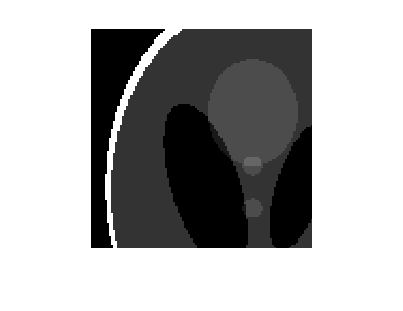

image_recon=reshape(v_final,total_smaller_pixel,total_smaller_pixel);
image_recon=image_recon(1:smaller_pixel_in_FoV,1:smaller_pixel_in_FoV);
figure;
imshow(GT);

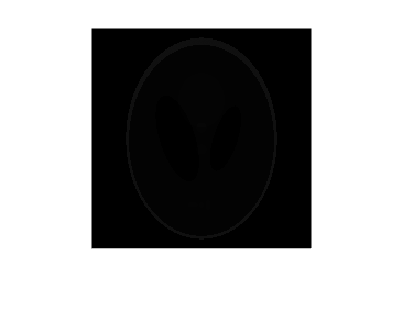

figure;
imshow(image_recon');

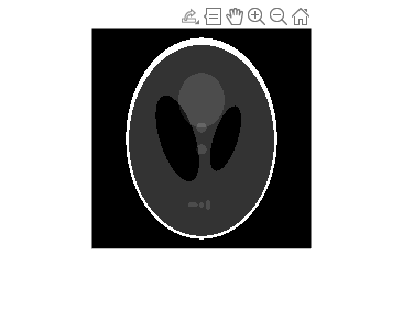

image_recon_normalized=(image_recon-min(image_recon(:)))/(max(image_recon(:))-min(image_recon(:)));
figure;
imshow(image_recon_normalized');

    0.1257



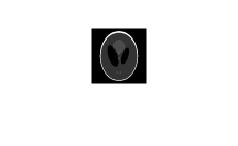

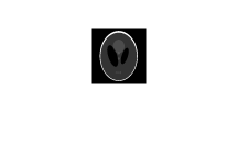

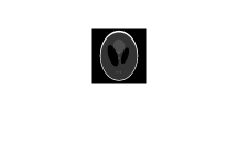

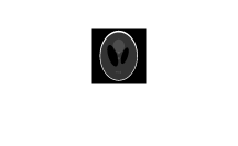

disp(sum(abs(GT-image_recon_normalized),"all")/smaller_pixel_in_FoV^2);


figure;
imshow(compressed_series{1,1});
figure;
imshow(compressed_series{1,2});
figure;
imshow(compressed_series{2,1});
figure;
imshow(compressed_series{2,2});
